**Classifying The Wisconsin Breast Cancer Data Set :**

In this case-study, it is required to devise a classifier for classifying Benign and Malignant Cells in the Wisconsin Breast Cancer data-set using a computational intelligence technique. The classifier is designed and evaluated using a systematic approach to data analytics. This data will need to be trained and used within a neural network.

The below section of code downloads the dataset from **UC Irvine Machine Learning Repository** and saves it locally:

filename='wdbc.data' 

filename = 'wdbc.data'

url = ['https://archive.ics.uci.edu/ml/machine-learning-databases/breast-cancer-wisconsin/' filename];

file_destination = filename;
% If the file has already been downloaded then this websave can be omitted
websave(file_destination,url);
% This line converts the data file, wdbc.data, into a table format so that it can used throughout this file
T = readtable(file_destination, 'FileType','text', 'Delimiter', 'comma')

T = 569×32 table
       Var1       Var2     Var3     Var4     Var5     Var6      Var7       Var8       Var9       Var10     Var11      Var12     Var13     Var14     Var15    Var16     Var17       Var18       Var19      Var20       Var21      Var22      Var23    Var24    Var25    Var26    Var27     Var28     Var29      Var30     Var31      Var32 
    __________    _____    _____    _____

% This removes the unneeded fields of ID and Result so it is only the data needed for the solution
input_dataOnly=T(:, 3:32);
% Converting this data to an array format for easier use
input_data=table2array(input_dataOnly);
% Setting output data array size to match the input data in size and a length of 2
output_data=zeros(size(input_dataOnly,1), 2)

output_data =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


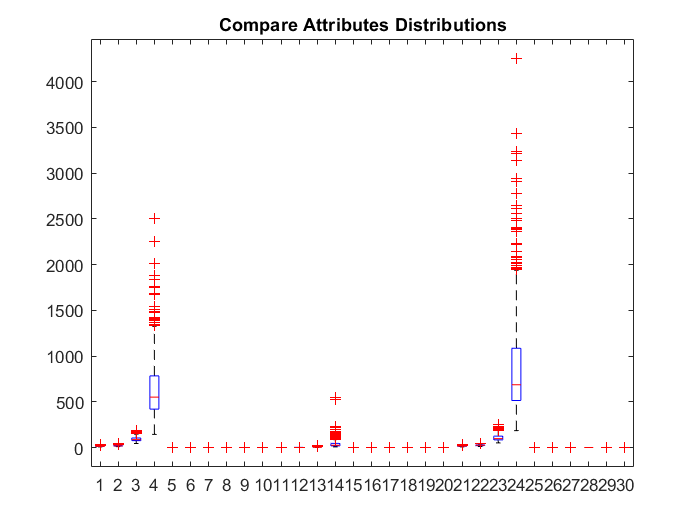

%Graphically inspect the data through box-plots. This shows distribution of data.
boxplot(input_data(:,:))
title('Compare Attributes Distributions')

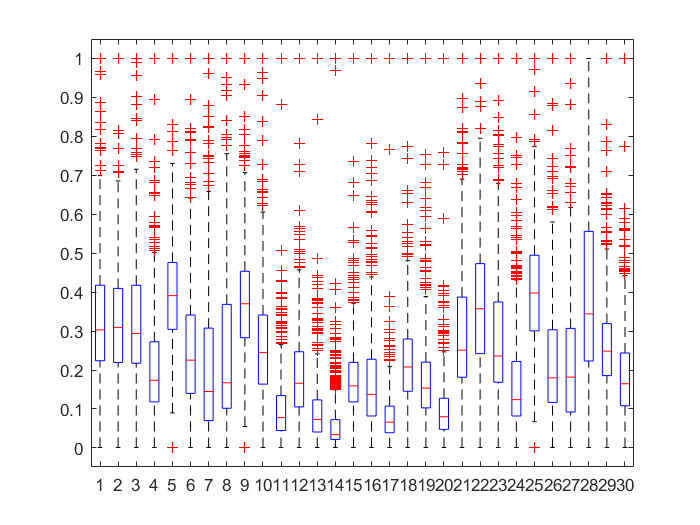

% The data-set attributes are varying in different ranges with too many outliers beyond the whiskers.
% For uniform weightage, we must normalise  all the attributes into the range [0.001, 1.0]. 
% This is done by appropriately scaling each of the attributes.
FP.ymin=0.001; FP.ymax=1.00;
[Y,PS] = mapminmax(input_data', FP);

% Inspect the normalised/scaled attributes (Y') instead of the previous values
boxplot(Y')

% There are still outliers for the attribute with the default whisker size of 1.5 times 
% of inter-quartile range (IQR). Let us appropriately change the whisker 
% size to 8 times of IQR and plot style to compact for better visualisation.
w=8;
figure, boxplot(Y', 'Whisker',w, 'PlotStyle','compact')

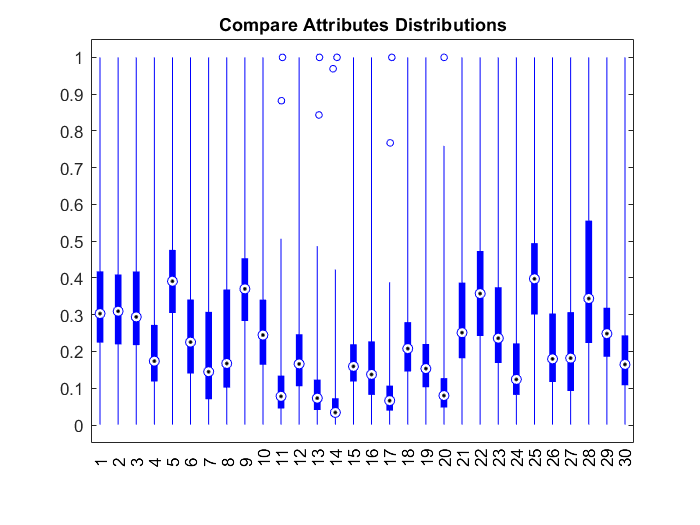

title('Compare Attributes Distributions')

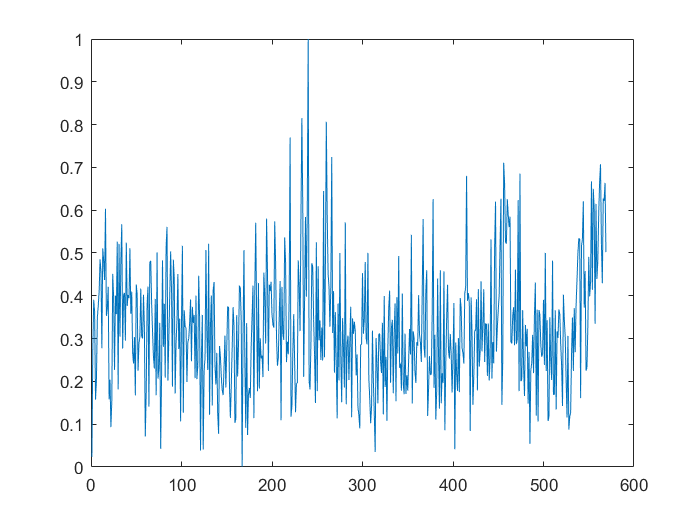

% There still outliers left with the  whisker size of 8 times of IQR.
% Plotting this can show the missing areas
y_data=Y';
plot(y_data(:,2))

% This section finds the data instnace that contains the outlier.
% Whisker is the term for the boundaries.
% An outlier is contained either above the upper whisker ( q3 + w × (q3 – q1) ) 
% or below the lower whisker ( q1 – w × (q3 – q1) ).

% Find the first quartile (q1).
q1 = quantile(y_data(:,2),0.25); 

% Find the third quartile (q3).
q3 = quantile(y_data(:,2),0.75);

% Find the the lower whisker.
lowerWhisker=q1 - w * (q3 - q1)

lowerWhisker = -1.3031

% Find the the upper whisker.
upperWhisker=q3 + w * (q3 - q1)

upperWhisker = 1.9319

meanValue=mean(y_data(:,2))

meanValue = 0.3246

outliers = (y_data(:,2)>upperWhisker)|(y_data(:,2)<lowerWhisker)

outliers = 569×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


NumOutliers=sum(outliers)

NumOutliers = 0

% Let us assign NaN (not a number) to the outlier(s).
y_data(outliers,2)=NaN;

% Plot the data with NaN values to identify the gaps.
plot(y_data(:,2))

%By comparing the above plot with the one without replacement, one can clearly see what data instance(s) are replaced with NaN.

% Now we replace the missing values (set to NaN). 
% Here we fill the missing data using linear interpolation and return the filled vector F and the logical vector TF. 
% The value 1 (true) in entries of TF corresponds to the values of F that were filled.
[F,TF] = fillmissing(y_data(:,2),'linear',1);

% Let us plot again the attribute after filling the missing value(s). 
% There should be no errors now if this was all executed correctly.
plot(F)

% This section now handles the output and target values of the data.
% Firstly, we set the target labels the output target to variable output_data (Zero values, Size(data-length x 2)).
for i=1:size(input_dataOnly,1)
    if (strcmp(table2cell(T(i,2)), 'M'))% if the table data from earlier is malignant at this cell index
        output_data(i,1)=1;             % then set the value to 1 so it can be found later
    else
        output_data(i,2)=1;             % then set the other table value to 1 so it can be found later
    end
end

% Assign all the attributes including the ones after outliers corrections as row vectors to the input patterns 'inputs'. 
inputs=[y_data(:,1), F, y_data(:,3:4)]';

% Assign the output target variables as row vectors to the output target patterns 'targets'.
targets=output_data';

The data has now been validated. This next section begins to build a **multi-layer perceptron (MLP)** network. 

The default network for function fitting  problems, **patternnet**, is a feedforward network with the default tan-sigmoid transfer function in the hidden layer, and a softmax transfer function in the output layer. The network has two output neurons, because there are two target values (categories M & B) associated with each input vector. Each output neuron represents a category.

When an input vector of the appropriate category is applied to the network, the corresponding neuron should produce a 1, and the other neurons should output a 0. To create and initialise the network, enter the following commands:

% Fix the seed for initialising random number generation, so that same values are initialised in the repeated runs.
rng(0)

% Initilise the network.
hiddenLayerSize =2; % multiple sizes where tested with 2 yeilding the best results
% Set the size of patternet and the type (trainlm = Levenberg-Marquardt backpropagation)
net = patternnet(hiddenLayerSize, 'trainlm');

Set up the division of data for training with cross-validation. 

The majority is needed for the training as it is the core of the model. The remaining is shared between the testing and validation.

net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio   = 15/100;
net.divideParam.testRatio  = 15/100;
% The below line sets the number of error expected for cross-validation.
% The results are still the same in terms of accuracy therefore this was
% not increased pasted the default 6.
%net.trainParam.max_fail = 20;

With these settings, the input vectors and target vectors will be randomly divided, with 70% used for training, 15% for validation and 15% for testing.

The following line trains the network using MatLab Toolboxs' train command.

[net,tr] = train(net,inputs,targets);

This will open the training window which we can interact with, stop or simply view during training.

The next section tests the network. After the network is trained, you can use it to compute the network outputs. 

The following code calculates the network outputs, errors and overall performance from toolbox functions.

outputs = net(inputs);
errors = gsubtract(targets,outputs);
performance = perform(net,targets,outputs)

performance = 0.0544

It is also possible to calculate the network performance only on the test set, by using the testing indices, which are located in the training record. View the network diagram.

view(net)

Plot the training, validation, and test performance.

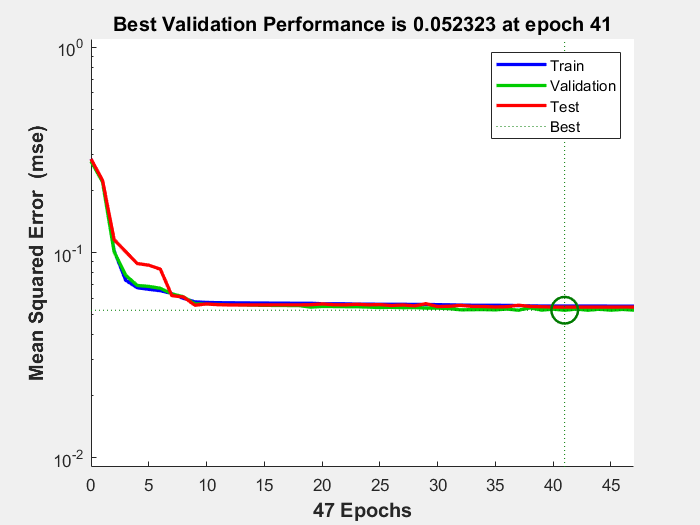

figure, plotperform(tr)

Below uses the plotconfusion function to plot the confusion matrix. It shows the various types of errors that occurred for the final trained network.  Through the training tool user interface (UI) further confusion matrices can be viewed for validation, testing training and overall.

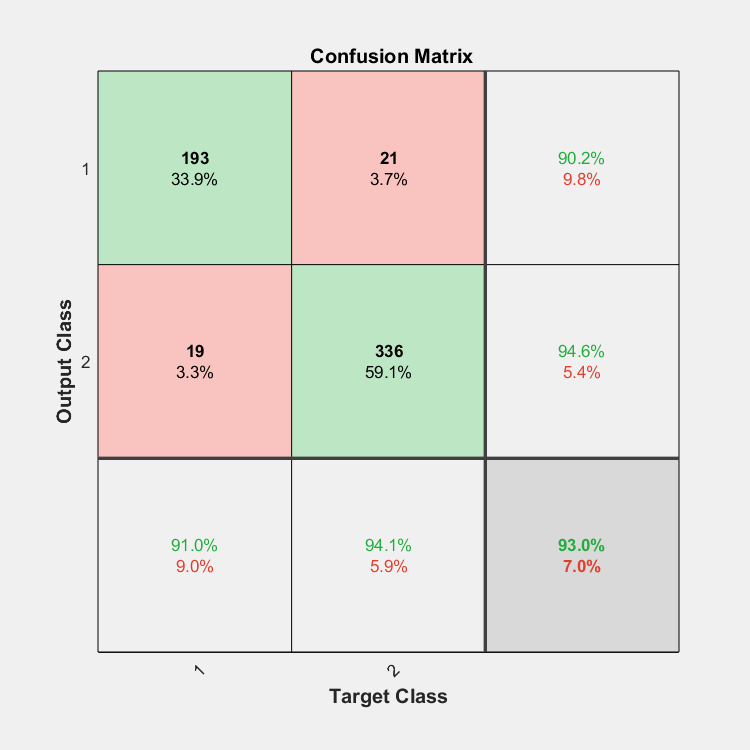

figure, plotconfusion(targets,outputs)

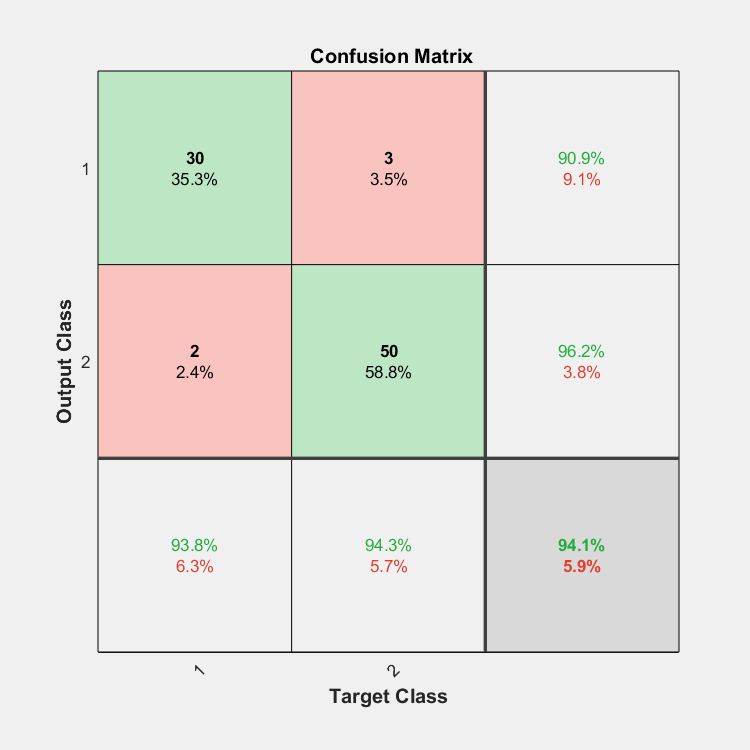

figure, testTargets=targets(:, tr.testInd);
testInputs=inputs(:, tr.testInd);
testOutputs=sim(net, testInputs);
plotconfusion(testTargets,testOutputs)